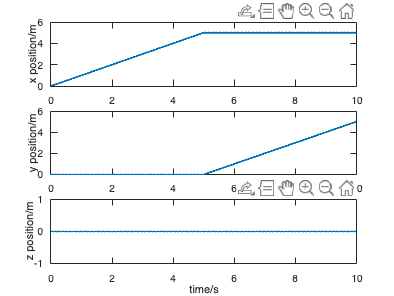

% This is the test of leader's state profiles

leaderState_x = [0 0 0]';
data = [];
dt = 0.01;
time = 0 : dt : 10;
timeArray = time;

for t = timeArray
    if t < 0.5*timeArray(end)
        leaderState_v = [1 0 0]';
    else 
        leaderState_v = [0 1 0]';
    end

    leaderState_x_update = leaderState_v;

    data = [data; t' leaderState_x' leaderState_v'];

    leaderState_x = leaderState_x + dt * leaderState_x_update;
end


% figure plots
figure
subplot(3,1,1)
plot(data(:,1),data(:,2),'-',LineWidth=2);   % plot of x positions
ylabel('x position/m')

subplot(3,1,2)
plot(data(:,1),data(:,3),'-',LineWidth=2);   % plot of y positions
ylabel('y position/m')

subplot(3,1,3)
plot(data(:,1),data(:,4),'-',LineWidth=2);   % plot of z positions
ylabel('z position/m')
xlabel('time/s')

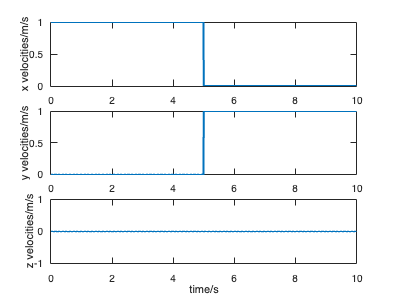




figure
subplot(3,1,1)
plot(data(:,1),data(:,5),'-',LineWidth=2);   % plot of x velocities
ylabel('x velocities/m/s')

subplot(3,1,2)
plot(data(:,1),data(:,6),'-',LineWidth=2);   % plot of y velocities
ylabel('y velocities/m/s')

subplot(3,1,3)
plot(data(:,1),data(:,7),'-',LineWidth=2);   % plot of z velocities
ylabel('z velocities/m/s')
xlabel('time/s')